# Area-to-point Kriging with ERT

In this live script, we will use area-to-point kriging to simulate fine-scale electrical conductivity field which respect a given spatial model as well as being consistent with the ERT inverted field.

## Generating the synthetic dataset

This section creates the data. `gen` struct store the parameter and `data_generation.m` compute everything.

Add the R2 folder in the path

addpath('R2');

The grid is defined by a number of cells in x and y as well as the length in unit in x and y

gen.xmax                = 100;  %total length in unit [m]
gen.ymax                = 15;   %total hight in unit [m]
gen.nx                  = 500;
gen.ny                  = 25;


Generation Method: All method generate with FFTMA a gaussian field. See more information in `data_generation.m`

% 'Normal'              with normal distribution \sim N(gen.mu,gen.std)
% 'LogNormal'           with normal distribution \sim log N(gen.mu,gen.std)
% 'fromRho':            log transform it with the parameter defined below 
% 'fromK':              generate with FFTMA a field of Hyraulic conductivity and log transform it with the parameter defined below 
gen.method              = 'fromLogPhi';

Parameters of the the spatial model

gen.samp                = 1;          % Method of sampling of K and g | 1: borehole, 2:random. For fromK or from Rho only
gen.samp_n              = 3;          % number of well or number of point
gen.covar(1).model      = 'exponential';
gen.covar(1).range0     = [4 40];
gen.covar(1).azimuth    = 0;
gen.covar(1).c0         = 1;
gen.covar               = kriginginitiaite(gen.covar);
gen.mu                  = -1.579;           % parameter of the first field. 
gen.std                 = sqrt(0.22361);

Parameters of the ERT (forward and inversion)

gen.Rho.method          = 'R2';             % 'Paolo' (default for gen.method Paolo), 'noise', 'RESINV3D'
gen.Rho.f ={};
gen.Rho.f.res_matrix    = 0;
gen.Rho.elec.spacing    = 2;                % in unit [m] | adapted to fit the fine grid
gen.Rho.elec.bufzone    = 2;                % number of electrod to skip 
gen.Rho.elec.config_max = 6000;             % number of configuration of electrode maximal 
gen.Rho.i.grid.nx       = 200;              % | adapted to fit the fine grid
gen.Rho.i.grid.ny       = 15;               % log-spaced grid  | adapted to fit the fine grid
gen.Rho.i.res_matrix    = 3;                % resolution matrix: 1-'sensitivity' matrix, 2-true resolution matrix or 0-none

Other parameters

gen.plotit              = true;             % display graphic or not (you can still display later with |script_plot.m|)
gen.saveit              = true;             % save the generated file or not, this will be turn off if mehod Paolo or filename are selected
gen.name                = '600x40';
gen.seed                = 8;

Run the function. The current selected option is to load a pre-computed dataset, comment/uncomment the lines below if you want to compute another the dataset. 

% fieldname = data_generation(gen);
% [fieldname, grid_gen, K_true, phi_true, sigma_true, K, sigma, Sigma, gen] = data_generation(gen);
fieldname = 'GEN-600x40_2017-12-21_15-44';

Figure of the ERT

Load the dataset

load(['ERT/result/' fieldname]);

Add some nice colormap, it can be downloaded [here](https://github.com/bids/colormap)

addpath('C:\Users\rafnu\Documents\MATLAB\Colormaps\')

Normal Score based on known distribution of Prim and Sec. If the forward/inversion Nscore is unknown, the Normal Score can be computed based on empirical CDF

Nscore.forward = @(x) (log(x./43)/1.4-gen.mu)./gen.std;
Nscore.inverse = @(x) 43.*exp(1.4*(x.*gen.std+gen.mu));
Sec=Sigma; 
Sec.d = Nscore.forward(Sigma.d);
Prim.d = Nscore.forward(sigma_true);
Prim.x = grid_gen.x; Prim.y = grid_gen.y; Prim.X = grid_gen.X; Prim.Y = grid_gen.Y;

% Nscore based on empirical CDF
% [kern.prior,kern.axis_prim] = ksdensity(sigma_true(:));
% parm.nscore=1;
% Nscore = nscore(kern, parm, 0);
% Sec=Sigma; 
% Sec.d = reshape(Nscore.forward(Sec.d(:)) ,numel(Sec.y),numel(Sec.x));
% Prim.d = reshape(Nscore.forward(sigma_true(:)), grid_gen.ny, grid_gen.nx);
% Prim.x = grid_gen.x; Prim.y = grid_gen.y; Prim.X = grid_gen.X; Prim.Y = grid_gen.Y;

Figure of the initial data

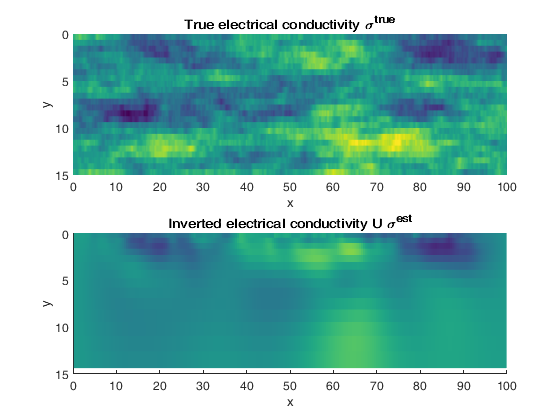

figure; colormap(viridis()); c_axis_n=log10([ min(sigma_true(:)) max(sigma_true(:)) ]);
subplot(2,1,1); surface(grid_gen.x, grid_gen.y, log10(sigma_true),'EdgeColor','none','facecolor','flat'); 
caxis(c_axis_n); title('True electrical conductivity \sigma^{true}'); xlabel('x'); ylabel('y'); set(gca,'Ydir','reverse');
subplot(2,1,2); surface(Sigma.x, Sigma.y, log10(Sigma.d),'EdgeColor','none','facecolor','flat'); 
caxis(c_axis_n); title('Inverted electrical conductivity U \sigma^{est}'); xlabel('x'); ylabel('y'); set(gca,'Ydir','reverse');

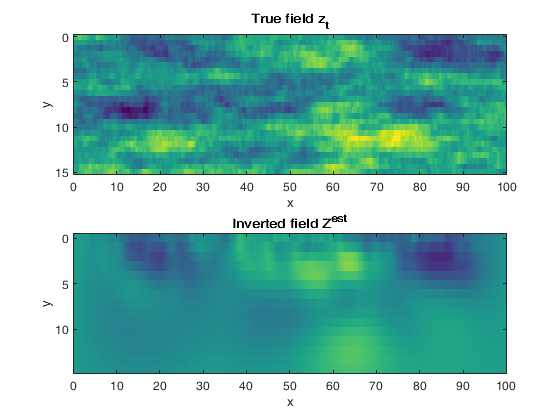


figure; colormap(viridis()); c_axis=[ min(Prim.d(:)) max(Prim.d(:))];
subplot(2,1,1); imagesc(grid_gen.x, grid_gen.y, Prim.d); caxis(c_axis); title('True field z_t'); xlabel('x'); ylabel('y'); 
subplot(2,1,2); imagesc(Sec.x, Sec.y, Sec.d); caxis(c_axis); title('Inverted field Z^{est}'); xlabel('x'); ylabel('y'); 

## Area-to-point Kriging

Built the matrix G which link the true variable Prim.d to the measured coarse scale d

G = zeros(numel(Sec.d), numel(Prim.d));
for i=1:numel(Sec.d)
    Res = reshape(Sigma.res(i,:)+Sigma.res_out(i)/numel(Sigma.res(i,:)),numel(Sec.y),numel(Sec.x));
    f = griddedInterpolant({Sec.y,Sec.x},Res,'linear');
    res_t = f({Prim.y,Prim.x});
    G(i,:) = res_t(:) ./sum(res_t(:));
end

Simulate a sampling. See `sampling_pt `for the description of the parameters (borehole or scattered points)

Prim_pt = sampling_pt(Prim,Prim.d,1,1);

Compute the covariance of the data error

Cm = inv(sqrtm(full(gen.Rho.i.output.R(gen.Rho.i.output.inside,gen.Rho.i.output.inside))));
Cmt = (eye(size(Sigma.res))-Sigma.res)*Cm;

Compute the covariance of the spatial model

covar = kriginginitiaite(gen.covar);
Cz = covar.g(squareform(pdist([Prim.X Prim.Y]*covar.cx)));
Cz=sparse(Cz);
Czd = Cz * G';
Cd = G * Czd;

Combine both covariance and built the Kriging System

Cd2 = Cd+Cmt;
Czh = Cz(Prim_pt.id,Prim_pt.id);
Czzh = Cz(Prim_pt.id,:);
Czhd = Czd( Prim_pt.id ,:);
CCa = [ Cd2 Czhd' ; Czhd Czh ];
CCb = [ Czd' ; Czzh' ];

Solve the kriging system

W=zeros(numel(Prim.x)*numel(Prim.y),numel(Sec.d(:))+Prim_pt.n);
parfor ij=1:numel(Prim.x)*numel(Prim.y)
     W(ij,:) = CCa \ CCb(:,ij);
end

Save everything

save(['ERT/result/' fieldname '_cond'],'W','Prim_pt','G','Nscore','Sec','Prim')

Figure of Area-to-point kriging

Load the file

load(['ERT/result/' fieldname '_cond'],'W','Prim_pt','G','Nscore','Sec','Prim')

Display the resolution matrix R

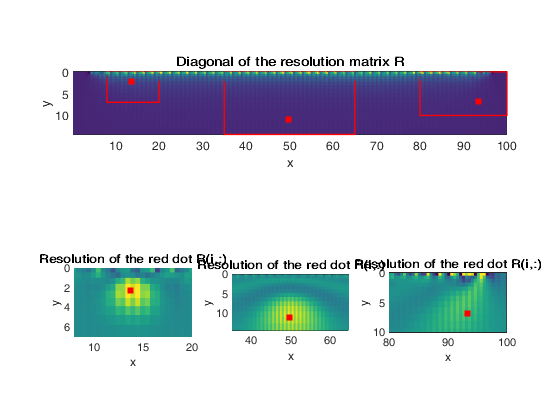

% OLD large grid: i=[1838 4525 8502]; th=.05; x_lim=[16 25; 35 65; 90 99]; y_lim=[-.12 7; -.12 19.57; -.12 8]; ccaxis=[-.02 .02; -.002 .002; -.01 .01];
i=[410 1498 2800]; th=.05; x_lim=[8 20; 35 65; 80 100]; y_lim=[-.007 7; -.007 14.37; -.007 10]; ccaxis=[-.05 .05; -.01 .01; -.02 .02];
figure; colormap(viridis())
subplot(2,numel(i),[1 numel(i)]);hold on; surface(Sec.X,Sec.Y,reshape(diag(Sigma.res),numel(Sec.y),numel(Sec.x)),'EdgeColor','none','facecolor','flat');  
scatter3(Sec.X(i),Sec.Y(i),100*ones(numel(i),1),'sr','filled')
for ii=1:numel(i)
    rectangle('Position',[x_lim(ii,1) y_lim(ii,1) range(x_lim(ii,:)) range(y_lim(ii,:))],'EdgeColor','r','linewidth',1)
end
view(2); axis tight equal; set(gca,'Ydir','reverse'); box on; xlabel('x');ylabel('y'); title('Diagonal of the resolution matrix R');
for ii=1:numel(i)
    subplot(2,numel(i),numel(i)+ii);hold on; surface(Sec.X,Sec.Y,reshape(Sigma.res(i(ii),:),numel(Sec.y),numel(Sec.x)),'EdgeColor','none','facecolor','flat');  scatter3(Sec.X(i(ii)),Sec.Y(i(ii)),100,'sr','filled')
    view(2); axis tight equal; set(gca,'Ydir','reverse'); box on; axis equal tight; xlabel('x');ylabel('y'); title('Resolution of the red dot R(i,:)'); xlim(x_lim(ii,:)); ylim(y_lim(ii,:));
    caxis(ccaxis(ii,:))
%     subplot(2,numel(i),2*numel(i)+ii);hold on; surface(Prim.X,Prim.Y,reshape(G(i(ii),:), numel(Prim.y), numel(Prim.x)),'EdgeColor','none','facecolor','flat'); scatter3(Sec.X(i(ii)),Sec.Y(i(ii)),100,'sr','filled')
%     view(2); axis tight equal; set(gca,'Ydir','reverse'); box on;  axis equal;  xlabel('x');ylabel('y'); xlim(x_lim(ii,:)); ylim(y_lim(ii,:))
end

Compute and plot the kriging map

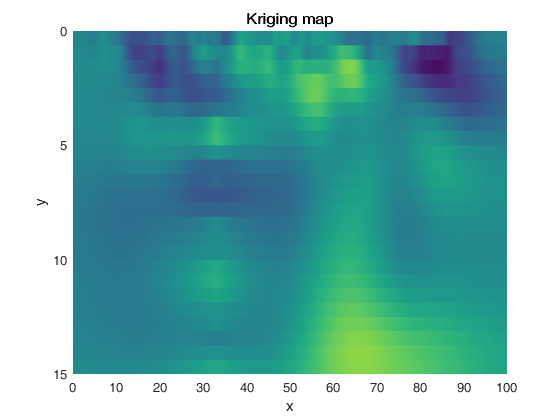

zh = reshape( W * [Sec.d(:) ; Prim_pt.d], numel(Prim.y),numel(Prim.x));

figure; colormap(viridis())
surf(Prim.x,Prim.y,zh,'EdgeColor','none','facecolor','flat'); caxis([-3 3])
view(2); set(gca,'Ydir','reverse'); xlabel('x');ylabel('y'); title('Kriging map')

Compute coarse G-transformed of the true fine scale and compare it to the inverted field

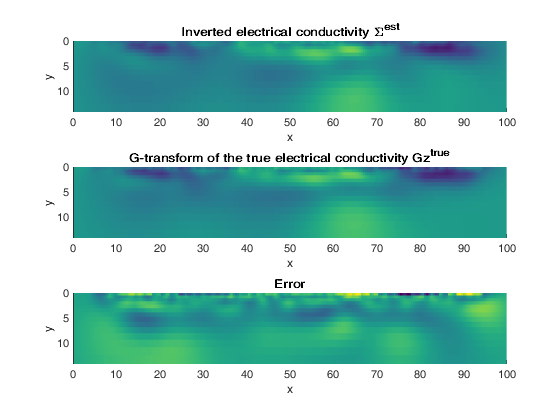

Test_Sec_d = reshape(G * Prim.d(:), numel(Sec.y), numel(Sec.x));
% zhtest = reshape( W * [Test_Sec_d(:) ; Prim_pt.d], ny, nx);

figure; colormap(viridis())
subplot(3,1,1);surface(Sec.X,Sec.Y,Sec.d,'EdgeColor','none','facecolor','flat'); view(2); set(gca,'Ydir','reverse'); caxis([-3 3]); xlabel('x');ylabel('y'); title('Inverted electrical conductivity \Sigma^{est}')
subplot(3,1,2);surface(Sec.X,Sec.Y,Test_Sec_d,'EdgeColor','none','facecolor','flat'); view(2); set(gca,'Ydir','reverse');  caxis([-3 3]);xlabel('x');ylabel('y');  title('G-transform of the true electrical conductivity Gz^{true}')
subplot(3,1,3);surface(Sec.X,Sec.Y,Test_Sec_d-Sec.d,'EdgeColor','none','facecolor','flat'); view(2); set(gca,'Ydir','reverse');  xlabel('x');ylabel('y'); title('Error')

## Simulation of eletrical conductivity fields with Area-to-point Kriging 

Using conditioning kriging we can easily generate conditional field 

rng('shuffle');
parm.n_real = 30; %500
zcs=nan(numel(Prim.y), numel(Prim.x),parm.n_real);
z=nan(numel(Sec.y), numel(Sec.x),parm.n_real);
covar = kriginginitiaite(gen.covar);
for i_real=1:parm.n_real
    zs = fftma_perso(covar, struct('x',Prim.x,'y',Prim.y));
    %zs = fftma_perso(gen.covar, grid_gen);
    zhs = W * [G * zs(:) ; zs(Prim_pt.id)./1.3];
    r = zh(:) + (zs(:) - zhs(:));
    zcs(:,:,i_real) = reshape( r, numel(Prim.y), numel(Prim.x));
    z(:,:,i_real)=reshape(G*r(:), numel(Sec.y), numel(Sec.x) );
end

Figure

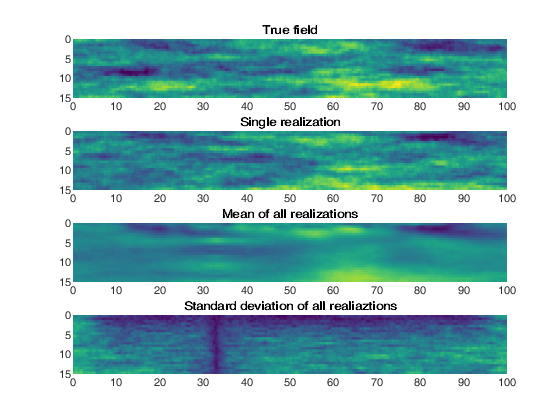

figure; colormap(viridis()); c_axis=[ -3 3];
subplot(4,1,1);surf(Prim.x, Prim.y, Prim.d,'EdgeColor','none','facecolor','flat'); caxis(c_axis);view(2); set(gca,'Ydir','reverse'); title('True field')
% hold on; scatter(Prim_pt.x,Prim_pt.y,'filled','r')
subplot(4,1,2);surf(Prim.x, Prim.y, zcs(:,:,1),'EdgeColor','none','facecolor','flat'); caxis(c_axis);view(2); set(gca,'Ydir','reverse'); title('Single realization')
subplot(4,1,3);surf(Prim.x, Prim.y, mean(zcs,3),'EdgeColor','none','facecolor','flat'); caxis(c_axis);view(2); set(gca,'Ydir','reverse'); title('Mean of all realizations')
subplot(4,1,4);surf(Prim.x, Prim.y, std(zcs,[],3),'EdgeColor','none','facecolor','flat'); view(2); set(gca,'Ydir','reverse'); title('Standard deviation of all realiaztions')

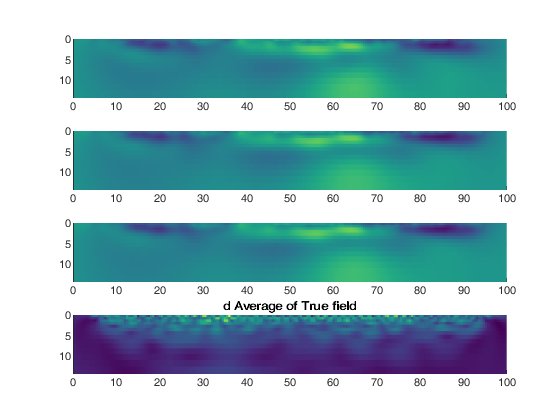

figure; colormap(viridis()); c_axis=[ -3 3];
subplot(4,1,1);surf(Sec.x, Sec.y, Sec.d,'EdgeColor','none','facecolor','flat'); caxis(c_axis); view(2);  set(gca,'Ydir','reverse');  
subplot(4,1,2);surf(Sec.x, Sec.y, z(:,:,1),'EdgeColor','none','facecolor','flat'); caxis(c_axis); view(2); set(gca,'Ydir','reverse'); 
subplot(4,1,3);surf(Sec.x, Sec.y, mean(z,3),'EdgeColor','none','facecolor','flat'); caxis(c_axis); view(2);set(gca,'Ydir','reverse');
subplot(4,1,4);surf(Sec.x, Sec.y, std(z,[],3),'EdgeColor','none','facecolor','flat');  title('d Average of True field');view(2); set(gca,'Ydir','reverse');

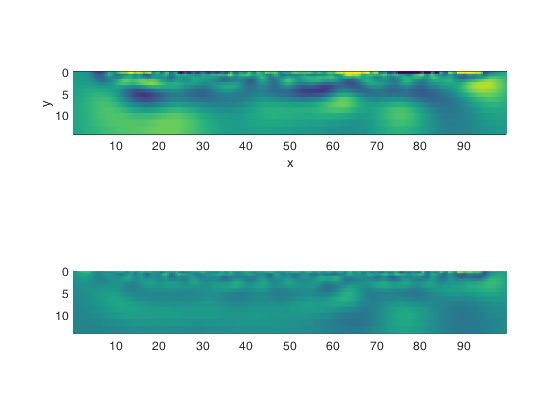

figure;colormap(viridis())
subplot(2,1,1);surface(Sec.X,Sec.Y,Test_Sec_d-Sec.d,'EdgeColor','none','facecolor','flat'); view(2); set(gca,'Ydir','reverse');  axis equal tight; box on; xlabel('x');ylabel('y'); caxis([-.6 .6]);
subplot(2,1,2);surf(Sec.x, Sec.y, mean(z,3)-Sec.d,'EdgeColor','none','facecolor','flat'); view(2); axis tight equal; set(gca,'Ydir','reverse'); caxis([-.6 .6])

Compute the Variogram and Histogram of realiaztions

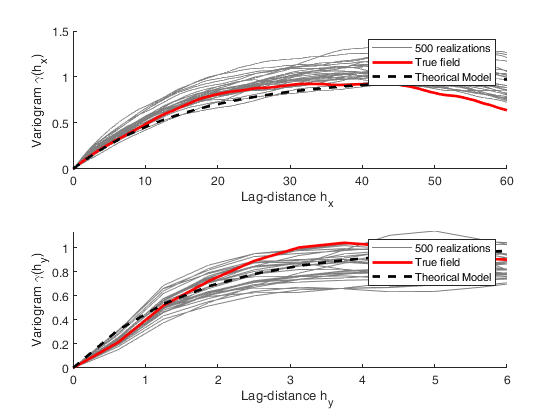

vario_x=nan(parm.n_real, numel(Prim.x));
vario_y=nan(parm.n_real,numel(Prim.y));
for i_real=1:parm.n_real
    r = zcs(:,:,i_real);
    %r = (r(:)-mean(r(:)))./std(r(:));
    [vario_x(i_real,:),vario_y(i_real,:)]=variogram_gridded_perso(reshape( r(:), numel(Prim.y), numel(Prim.x)));
end
[vario_prim_x,vario_prim_y]=variogram_gridded_perso(Prim.d);

figure;
subplot(2,1,1);  hold on; 
h1=plot(Prim.x(1:2:end),vario_x(:,1:2:end)','b','color',[.5 .5 .5]);
h2=plot(Prim.x,vario_prim_x,'-r','linewidth',2);
h3=plot(Prim.x,1-covar.g(Prim.x*covar.cx(1)),'--k','linewidth',2);
xlim([0 60]); xlabel('Lag-distance h_x ');ylabel('Variogram \gamma(h_x)')
legend([h1(1) h2 h3],'500 realizations','True field','Theorical Model')
subplot(2,1,2); hold on; 
h1=plot(Prim.y,vario_y','b','color',[.5 .5 .5]);
h2=plot(Prim.y,vario_prim_y,'-r','linewidth',2);
h3=plot(Prim.y,1-covar.g(Prim.y*covar.cx(4)),'--k','linewidth',2);
xlim([0 6]); xlabel('Lag-distance h_y ');ylabel('Variogram \gamma(h_y)')
legend([h1(1) h2 h3],'500 realizations','True field','Theorical Model')

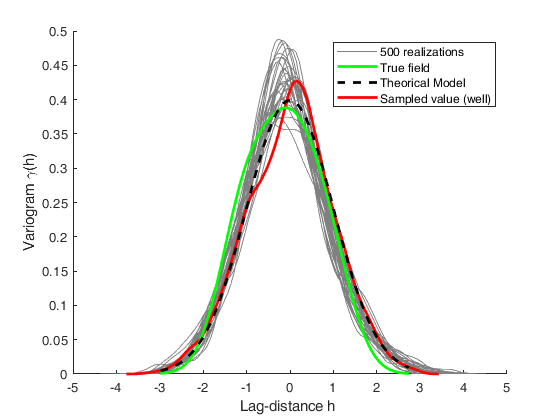

figure; hold on; colormap(viridis())
for i_real=1:parm.n_real
    r=zcs(:,:,i_real);
    %r = (r(:)-mean(r(:)))./std(r(:));
    [f,xi] = ksdensity(r(:));
    h1=plot(xi,f,'b','color',[.5 .5 .5]);
end
[f,xi] = ksdensity(Prim.d(:));
h4=plot(xi,f,'-r','linewidth',2);
[f,xi] = ksdensity(Prim_pt.d(:));
h2=plot(xi,f,'-g','linewidth',2);
h3=plot(xi,normpdf(xi),'--k','linewidth',2);
xlabel('Lag-distance h ');ylabel('Variogram \gamma(h)')
legend([h1 h2 h3 h4],'500 realizations','True field','Theorical Model','Sampled value (well)')

## Forward simulation

 Put the realization in the forward ERT

parm.n_real=500;
fsim_pseudo=nan(numel(gen.Rho.f.output.pseudo),parm.n_real);
fsim_resistance=nan(numel(gen.Rho.f.output.resistance),parm.n_real);
rho = 1000./Nscore.inverse(zcs);
for i_real=1:parm.n_real
    f={};
    f.res_matrix        = gen.Rho.f.res_matrix;
    f.grid              = gen.Rho.f.grid;    
    f.header            = 'Forward';  % title of up to 80 characters
    f.job_type          = 0;
    f.filepath          = ['data_gen/IO-file-' num2str(i_real) '/'];
    f.readonly          = 0;
    f.alpha_aniso       = gen.Rho.f.alpha_aniso;
    f.elec_spacing      = gen.Rho.f.elec_spacing;
    f.elec_id           = gen.Rho.f.elec_id;
    f.rho               = rho(:,:,i_real);
    f.num_regions       = gen.Rho.f.num_regions;
    f.rho_min           = gen.Rho.f.rho_min;
    f.rho_avg           = gen.Rho.f.rho_avg;
    f.rho_max           = gen.Rho.f.rho_max;
    
    mkdir(f.filepath)
    f                   = Matlat2R2(f,gen.Rho.elec); % write file and run forward modeling
    fsim_pseudo(:,i_real) = f.output.pseudo;
    fsim_resistance(:,i_real) = f.output.resistance;
end

Save

save(['result/' fieldname '_sim'],'zcs','fsim_pseudo','fsim_resistance')

Figure of forward simulation

Load the file

load(['result/' fieldname '_sim'])

 Compute the misfit

fsim_misfit=nan(numel(gen.Rho.f.output.resistancewitherror),parm.n_real);
err=nan(1,parm.n_real);
for i_real=1:parm.n_real  
    fsim_misfit(:,i_real) = (fsim_resistance(:,i_real) - gen.Rho.f.output.resistancewitherror) ./ (gen.Rho.i.a_wgt + gen.Rho.i.b_wgt*gen.Rho.f.output.resistancewitherror);
    err(i_real) = sqrt(mean(fsim_misfit(:,i_real).^2));
end

Plot the histogram of the error

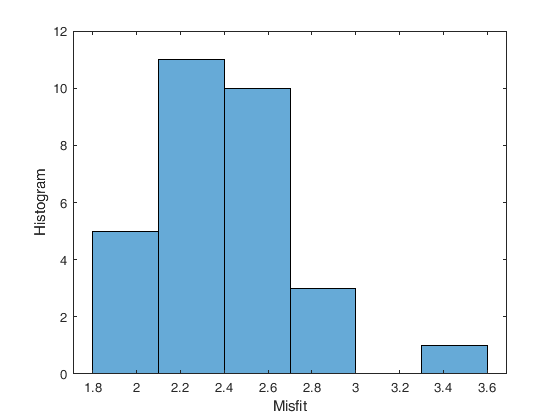

figure; histogram(err);
xlabel('Misfit'); ylabel('Histogram')

Plot...

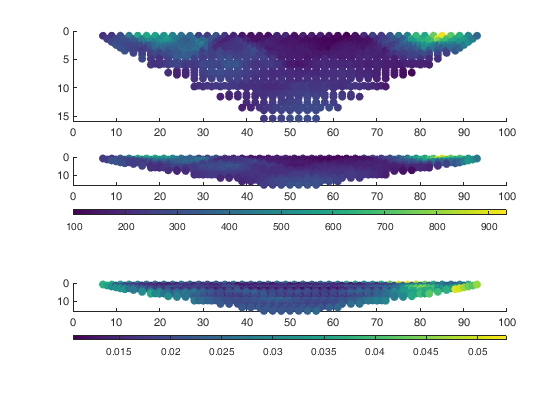

figure; colormap(viridis());c_axis=[min(gen.Rho.f.output.pseudo(:)) max(gen.Rho.f.output.pseudo(:))]; 
subplot(3,1,1); scatter(gen.Rho.f.pseudo_x,gen.Rho.f.pseudo_y,[],gen.Rho.f.output.pseudo,'filled');set(gca,'Ydir','reverse');caxis(c_axis);  xlim([0 100]); ylim([0 16]);
subplot(3,1,2); scatter(gen.Rho.f.pseudo_x,gen.Rho.f.pseudo_y,[],mean(fsim_pseudo,2),'filled');set(gca,'Ydir','reverse');caxis(c_axis); colorbar('southoutside');xlim([0 100]); ylim([0 16])
subplot(3,1,3); scatter(gen.Rho.f.pseudo_x,gen.Rho.f.pseudo_y,[],std(fsim_pseudo,[],2)./mean(fsim_pseudo,2),'filled');set(gca,'Ydir','reverse'); colorbar('southoutside');xlim([0 100]); ylim([0 16])

Plot

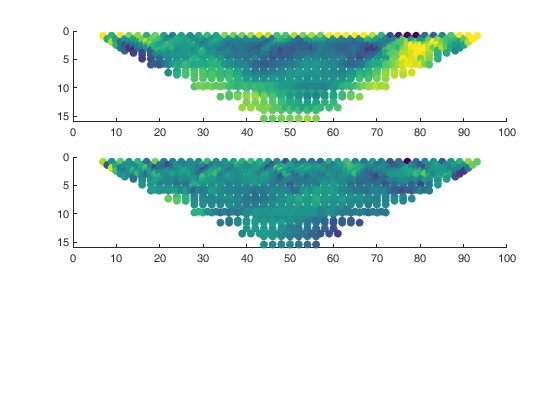

figure;colormap(viridis()); c_axis=[min(gen.Rho.f.output.pseudo(:)) max(gen.Rho.f.output.pseudo(:))];
subplot(3,1,1); scatter(gen.Rho.f.pseudo_x,gen.Rho.f.pseudo_y,[],(mean(fsim_pseudo,2)-gen.Rho.f.output.pseudo)./gen.Rho.f.output.pseudo,'filled');set(gca,'Ydir','reverse'); xlim([0 100]); ylim([0 16])
caxis([-.1 .1])
subplot(3,1,2); scatter(gen.Rho.f.pseudo_x,gen.Rho.f.pseudo_y,[],(gen.Rho.i.output.pseudo-gen.Rho.f.output.pseudo)./gen.Rho.f.output.pseudo,'filled');set(gca,'Ydir','reverse'); xlim([0 100]); ylim([0 16])
caxis([-.05 .05])

Plot...

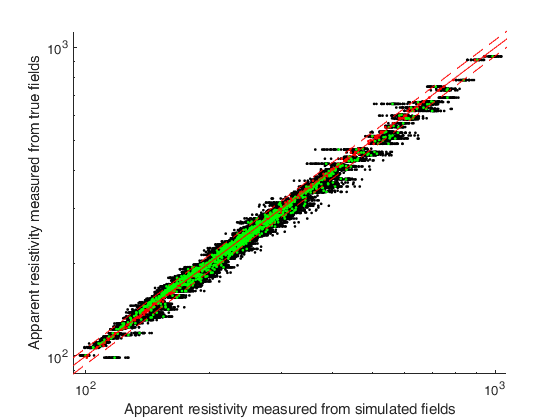

figure; hold on;
for i_real=1:parm.n_real  
    scatter(fsim_pseudo(:,i_real),gen.Rho.f.output.pseudo,'.k');
end
scatter(gen.Rho.i.output.pseudo,gen.Rho.f.output.pseudo,'.r');
scatter(mean(fsim_pseudo,2),gen.Rho.f.output.pseudo,'.g');
x=[floor(min(fsim_pseudo(:))) ceil(max(fsim_pseudo(:)))];
plot(x,x,'-r'); 
plot(x,x-x*3*gen.Rho.i.b_wgt,'--r'); 
plot(x,x+x*3*gen.Rho.i.b_wgt,'--r'); 
xlabel('Apparent resistivity measured from simulated fields');
ylabel('Apparent resistivity measured from true fields');
set(gca, 'YScale', 'log'); set(gca, 'XScale', 'log')